# Gaussian processes

Here we will study Gaussian processes or random fields. We simulate spatial data, perform parameter estimation and prediction (Kriging).

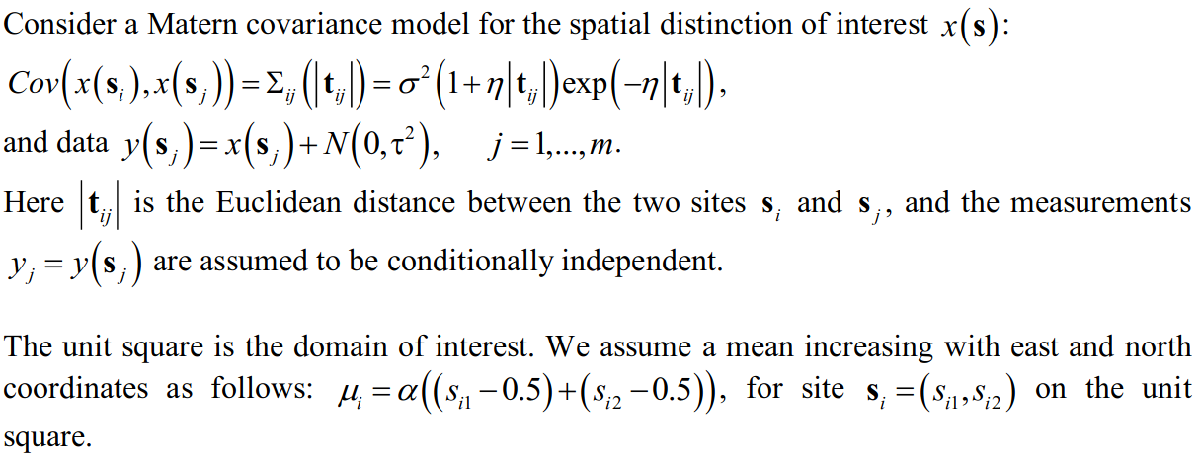

## Task 1

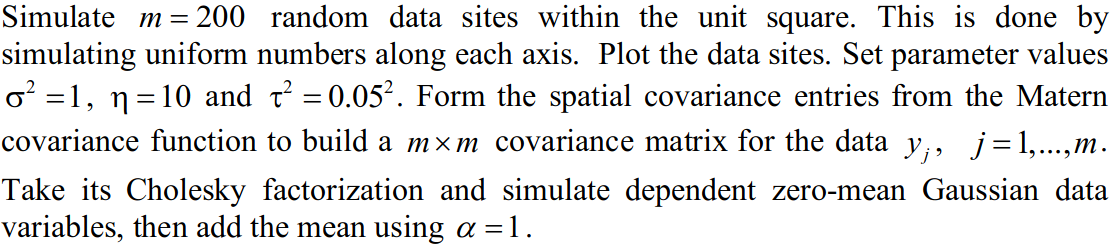

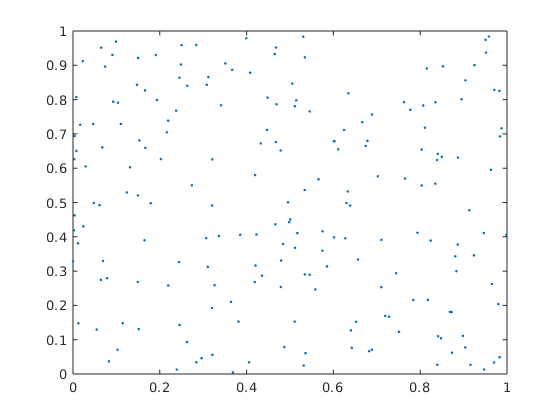

m = 200;      % Number of measurments
sigma = 1;    % Covariance parameter
eta = 10;     % Covariance parameter
tau = 0.05;   % Covariance parameter (Measurment Noise std)
alpha = 1;    % Regression parameter (Mean parameter)

s = rand(200,2);
figure
plot(s(:,1),s(:,2),'.');


C = zeros(m,m);
for i = 1:m
    for j = 1:m
        eucl_dist = norm(s(i)-s(j));
        C(i,j) = sigma^2 * (1 + eta*eucl_dist) * exp(-eta * eucl_dist);
    end
end

Sigma = C + eye(m)*tau^2;

%Y = chol(C)*rand(m,1) + tau*randn(m,1);

Y = chol(Sigma)*randn(m,1);    % Y ~ N(0,Sigma)

H = zeros(m,1);
for i = 1:m
    H(i) = (s(i,1) - 0.5) * (s(i,2) - 0.5);
end

Y = Y + alpha * H;             % Y ~ N(alpha*H,C)

## Task 2

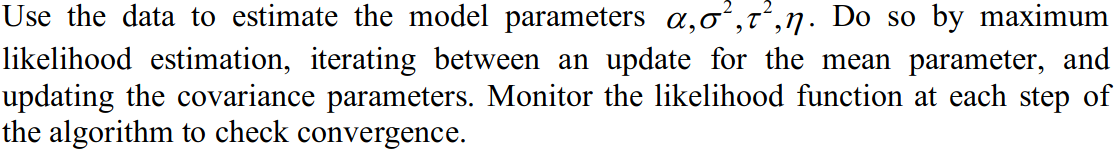

Log likelihood of multivariate gaussian:


$$l\left(\mathbf{Y}\;|\;\alpha ,\theta \;\right)=-\frac{1}{2}\mathrm{log}\;\left|\Sigma \right|-\frac{1}{2}\;{\mathbf{Z}}^{\prime } {\;\Sigma }^{-1} \;\mathbf{Z}$$



$$\mathbf{Z}=\mathbf{Y}-\mathbf{H}\alpha$$



$$\theta =\left\lbrack \begin{array}{ccc}
\sigma^2  & \tau^2  & \eta 
\end{array}\right\rbrack$$


Derivate loglikelihood with respect to $\theta$:

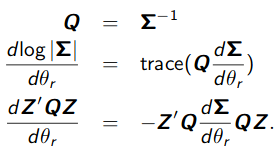

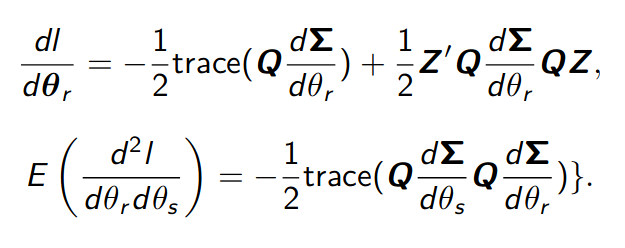

Derivate loglikelihood with respect to $\alpha$:


$$\frac{d}{\textrm{d}\alpha }l=-{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{H}\;\alpha +{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{Y}$$


Set to zero:


$$\alpha^ˆ ={{\left({\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{H}\;\right)}^{-1} \;{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{Y}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;}^{\prime }$$


NB: This estimated $\alpha \;$is a function of $\theta$ thus we update them iteratively.

  $\beta =\alpha$

dC_eta = zeros(m,m);
dC_sigma = zeros(m,m);
for i = 1:m
    for j = 1:m
        eucl_dist = norm(s(i)-s(j));
        dC_sigma(i,j) = 2*sigma * (1 + eta*eucl_dist)*exp(-eta * eucl_dist);
        dC_eta(i,j) = sigma^2 *( (eucl_dist)*exp(-eta * eucl_dist) + (1 + eta*eucl_dist)*exp(-eta * eucl_dist)*(-eucl_dist) );
    end
end
dSigma_eta = dC_eta + eye(m)*tau^2;
dSigma_sigma = dC_sigma + eye(m)*tau^2;
dSigma_tau = Sigma + 2*tau*eye(m);

## Task 3